# Task 1: Model Development

## Introduction:

This script aims to develop and test, in collaboration with Simulink, a model for the kinodynamics of a hexacopter for the A3S exam. Once developed and validated, this model will be used for the next tasks. 

addpath("Models and Auxiliary Functions\")

### Kinematics: 

The first step in developing the model is coding a kinematic block that relates the linear and angular velocity of the platform with its pose. Following the directions of the problem statement, body kinematics are chosen. Attitude is representing using quaternions, given their numerical advantages. Quaternion normalization is introduced to be able to handle longer simulations. It follows the quaternion convention described in the slides. Note that rotations are described by their active representation, which corresponds with the change of basis matrix from the rotated frame to the original one. 

#### Test 1: 

This test involves a non-null linear velocity and null angular velocity. The idea is to test only one part at a time: 

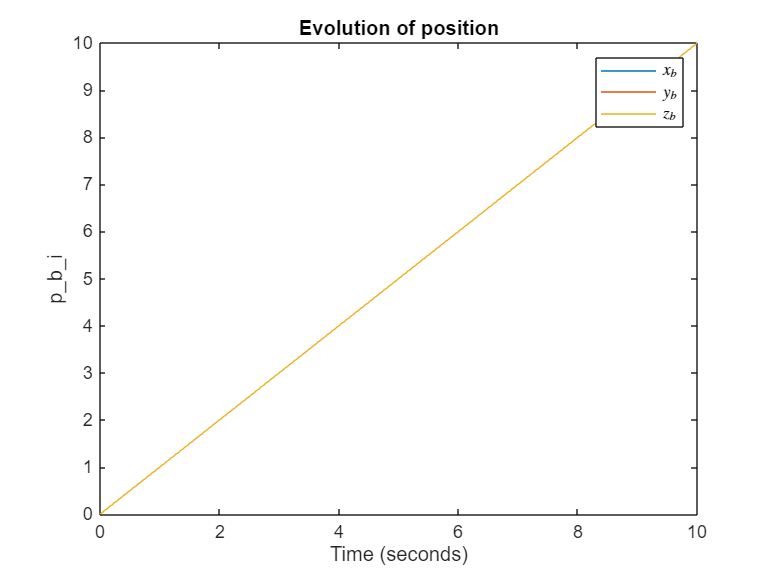

%Test number 1: only position kinematics: 
p_b_i_0=[0;0;0];
q_0=[1;0;0;0];

v_b=[1;1;1];
omega_b=zeros(3,1);

simout=sim("Kinematics_Model.slx");

figure(1)
clf
plot(simout.p_b_i)
hold on
title('Evolution of position')
legend('$x_b$','$y_b$','$z_b$','Interpreter','latex')

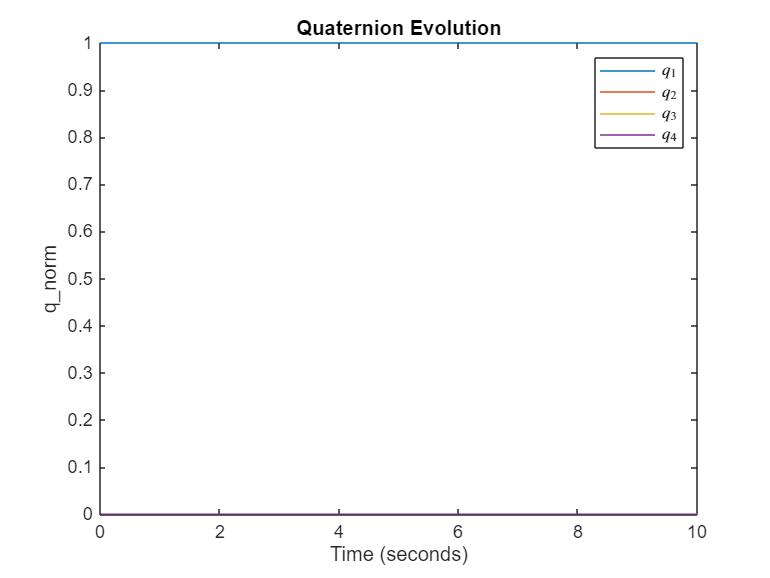


figure(2)
clf
plot(simout.q)
hold on
title('Quaternion Evolution')
legend('$q_1$','$q_2$','$q_3$','$q_4$','Interpreter','latex')

The first test is successful.

#### Test 2: 

Now the goal is to test the model with null linear velocity and non-null angular velocity. 

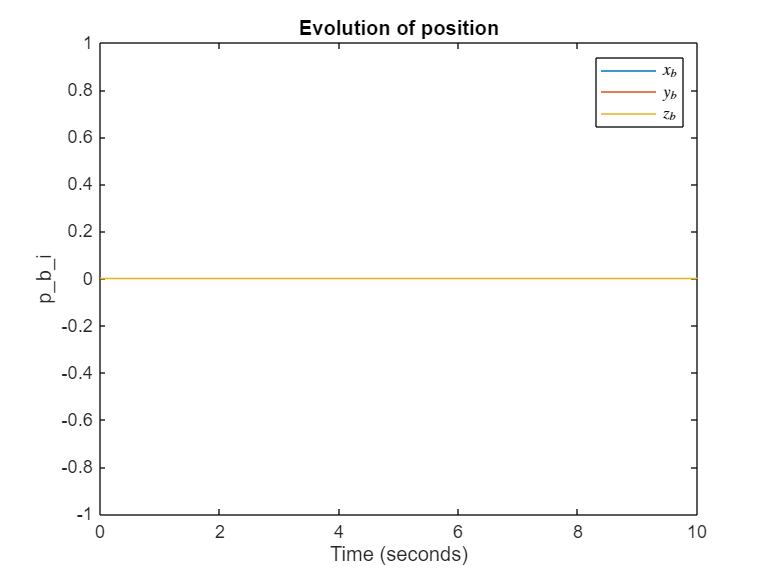

%Test number 2: Only angular kinematics: 
p_b_i_0=[0;0;0];
q_0=[1;0;0;0];

v_b=[0;0;0];
omega_b=[2*pi/20;0;0]; %[rad/s]
simout=sim("Kinematics_Model.slx");

figure(1)
clf
plot(simout.p_b_i)
hold on
title('Evolution of position')
legend('$x_b$','$y_b$','$z_b$','Interpreter','latex')

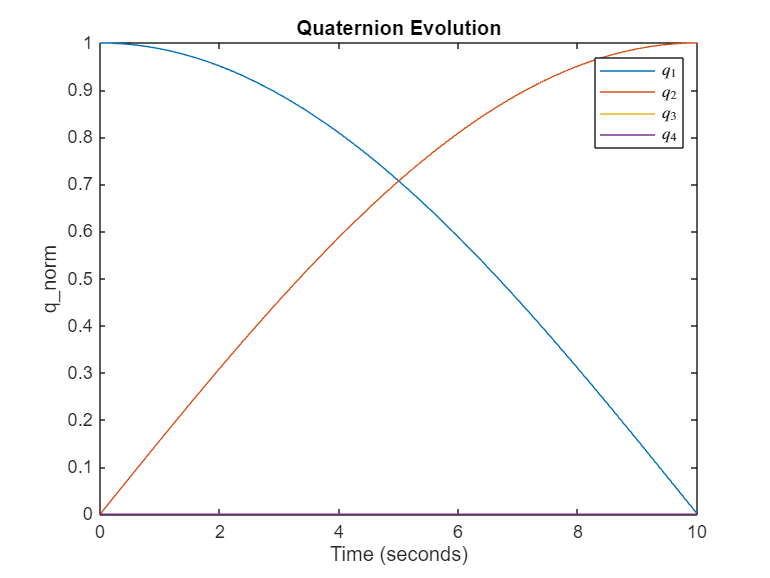


figure(2)
clf
plot(simout.q)
hold on
title('Quaternion Evolution')
legend('$q_1$','$q_2$','$q_3$','$q_4$','Interpreter','latex')

It also passes the second test. 

#### Test 3: combined attitude and position kinematics: 

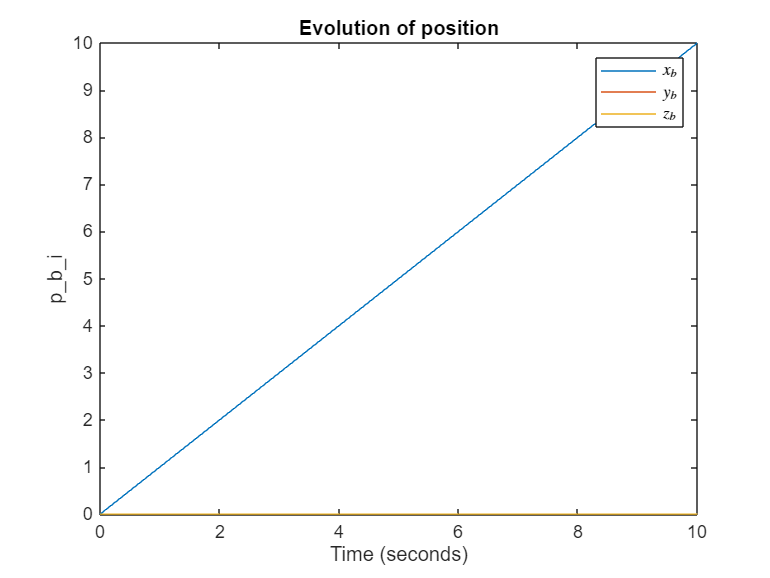

%Test number 3: combined kinematics 
p_b_i_0=[0;0;0];
q_0=[1;0;0;0];

v_b=[1;0;0];
omega_b=[2*pi/10;0;0]; %[rad/s]
simout=sim("Kinematics_Model.slx");

figure(1)
clf
plot(simout.p_b_i)
hold on
title('Evolution of position')
legend('$x_b$','$y_b$','$z_b$','Interpreter','latex')

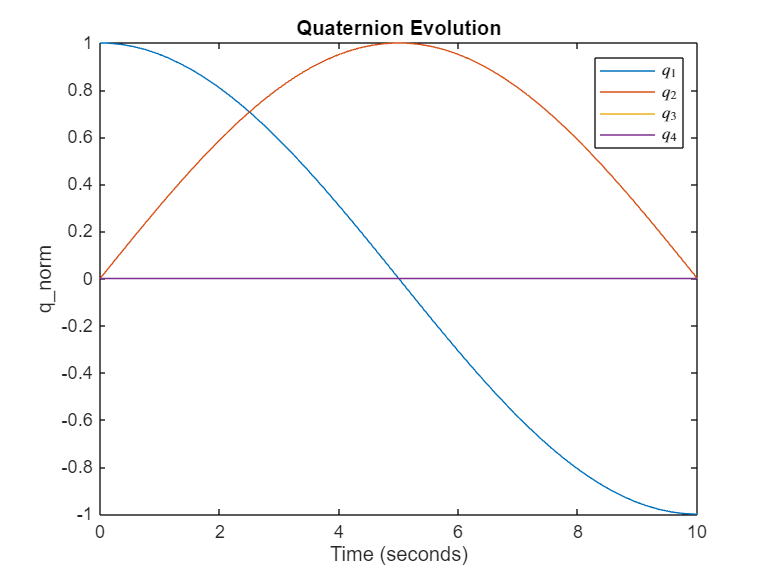


figure(2)
clf
plot(simout.q)
hold on
title('Quaternion Evolution')
legend('$q_1$','$q_2$','$q_3$','$q_4$','Interpreter','latex')

This test is also passed. 

### Kinematic testing conclusions: 

The kinematics module has been succesfully tested. Note that in this implementation, there is no quaternion shadowset. Indeed, in cases with a period of 10 and a stop time of 10 we can see that the final quaternion is actually the opposite of the initial one. However, for the purposes of integrating position and determining the relevant DCM, this is no issue. 

## Dynamics with gravity wrench:

The kinematic subsystem developed so far is now augmented with the dynamic model for the UAV. To begin with, only gravity loads will be considered. The system will then be verified using two different tests. Afterwards, the aerodynamics and propeller wrench will be included in the model. 

First, let us define the relevant physical parameters for the model: 

%Define geometric and inertial model parameters: 
UAV.Nr = 6; %number of rotors

UAV.m = 1.2; %[kg] UAV mass

UAV.J = diag([0.01 0.01 0.018]); % [kg m^2] inertia matrix

UAV.r_bg = [0 0 0]'; %[m] center of mass location in the body frame -> note I change it to a column vector. 
UAV.S = UAV.m*cross_matrix(UAV.r_bg); % [kg m] static moment

%Use these to define the relevant matrices: 
UAV.MM=[UAV.m*eye(3,3),UAV.S';UAV.S,UAV.J];
UAV.MM_inv=inv(UAV.MM);

%Specify gravitational acceleration: 
g=9.81; %[m/s^2]

#### Test Case 1: Gravity

Given that it is assumed that B is at the center of gravity of the overall platform, it is possible to study a problem where the system just falls like a particle under the effect of gravity. Let's proceed with it: 

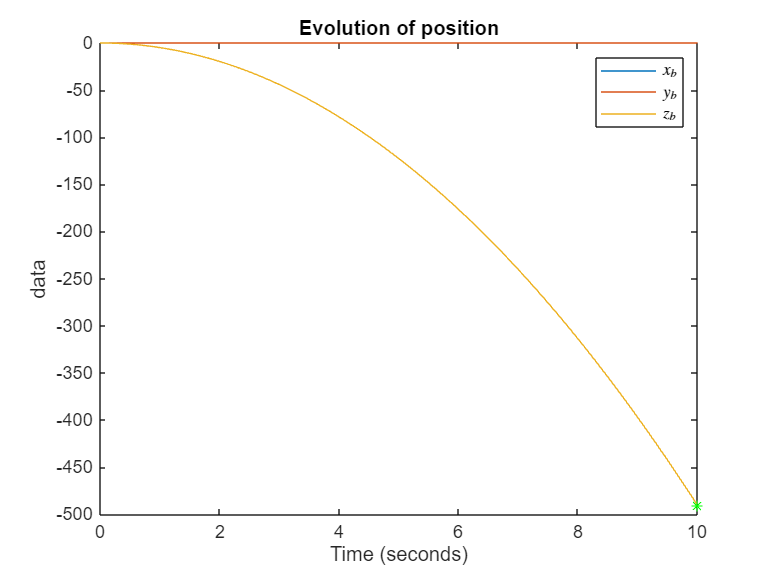

%Specify initial conditions for kinematics: 
p_b_i_0=[0;0;0];
q_0=[1;0;0;0];
%Specify initial conditions for dynamics: 
v_b_0=[0;0;0];
omega_b_0=[0;0;0];
nu_b_0=[v_b_0;omega_b_0];
%Simulate:
simout=sim("Gravity_Dynamics_Model.slx");
%Plot position and attitude: 
figure(1)
clf
plot(simout.p_b_i)
hold on
plot(10,-g*10^2/2,'g*')
title('Evolution of position')
legend('$x_b$','$y_b$','$z_b$','Interpreter','latex')

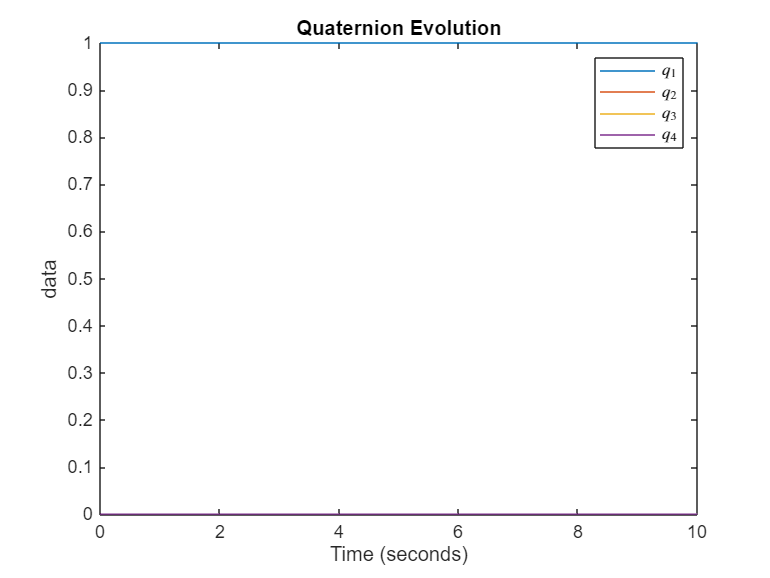


figure(2)
clf
plot(simout.q)
hold on
title('Quaternion Evolution')
legend('$q_1$','$q_2$','$q_3$','$q_4$','Interpreter','latex')

This implementation passes the first test.

#### Test Case 2: Stability of Rotation Around Principal Axes

Since we are considering the B axes to be principal inertia axes, we can further verify the implementation by checking the stability of rotation about the principal axes. To that end, we'll try three different cases: 

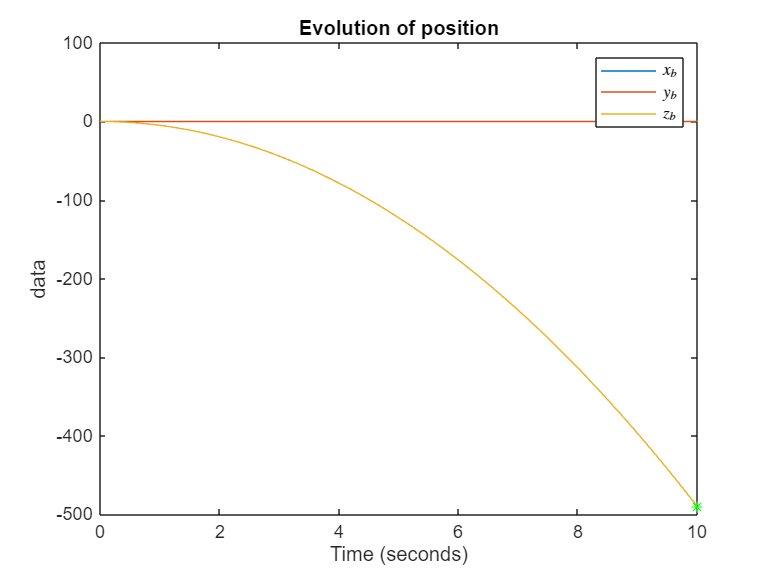

%Case 1: Rotation about x -> minor axis (coincides with intermediate axis)
p_b_i_0=[0;0;0];
q_0=[1;0;0;0];

v_b_0=[0;0;0];
omega_b_0=[2*pi;1e-4;1e-4]; %[rad/s]
nu_b_0=[v_b_0;omega_b_0];

simout=sim("Gravity_Dynamics_Model.slx");

figure(1)
clf
plot(simout.p_b_i)
hold on
plot(10,-g*10^2/2,'g*')
title('Evolution of position')
legend('$x_b$','$y_b$','$z_b$','Interpreter','latex')

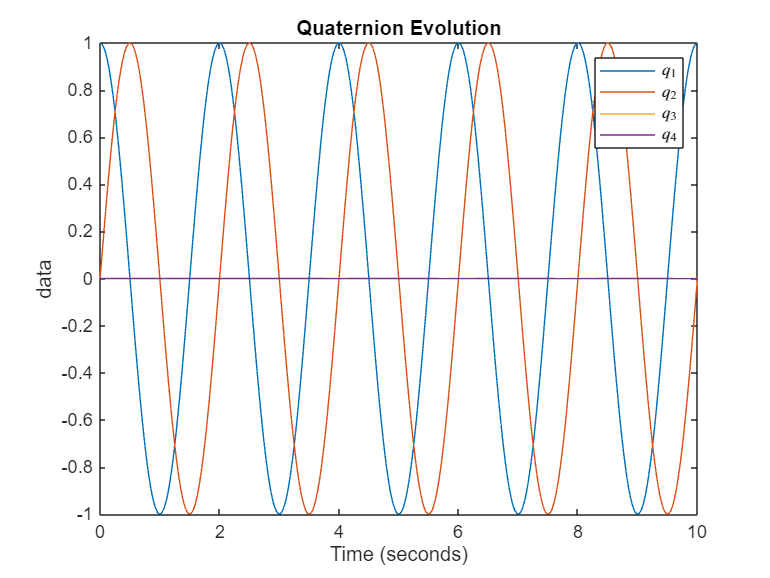


figure(2)
clf
plot(simout.q)
hold on
title('Quaternion Evolution')
legend('$q_1$','$q_2$','$q_3$','$q_4$','Interpreter','latex')

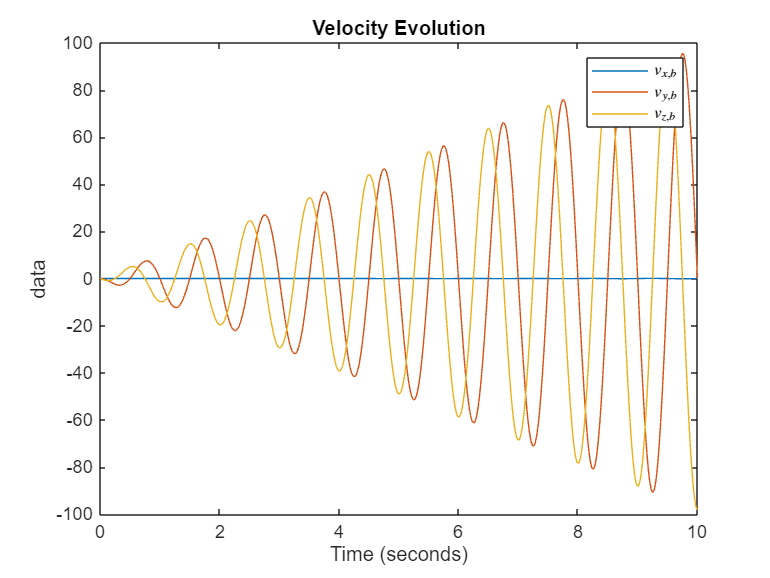



figure(3)
clf
plot(simout.v_b)
hold on
title('Velocity Evolution')
legend('$v_{x,b}$','$v_{y,b}$','$v_{z,b}$','Interpreter','latex')

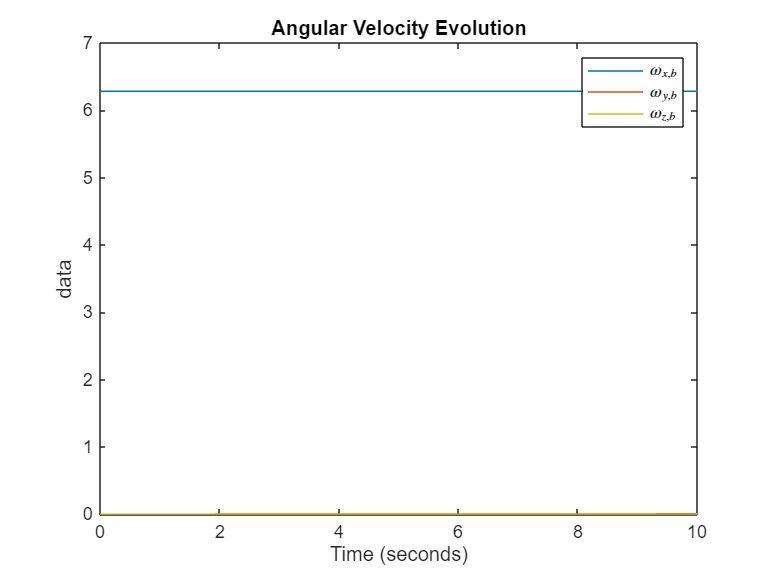


figure(4)
clf
plot(simout.omega_b)
hold on
title('Angular Velocity Evolution')
legend('$\omega_{x,b}$','$\omega_{y,b}$','$\omega_{z,b}$','Interpreter','latex')

The implementation passes this first case. Now test the y axis: 

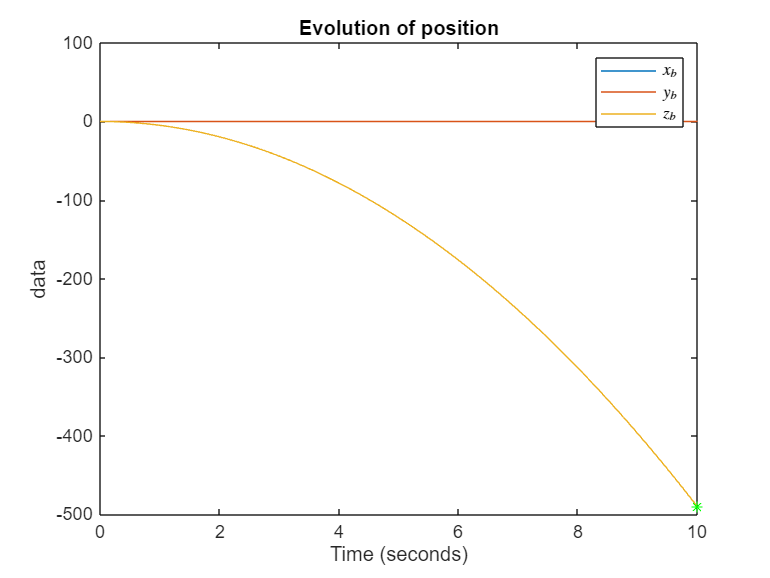

%Case 2: Rotation about y -> minor axis (coincides with intermediate axis)
p_b_i_0=[0;0;0];
q_0=[1;0;0;0];

v_b_0=[0;0;0];
omega_b_0=[1e-4;2*pi;1e-4]; %[rad/s]
nu_b_0=[v_b_0;omega_b_0];

simout=sim("Gravity_Dynamics_Model.slx");

figure(1)
clf
plot(simout.p_b_i)
hold on
plot(10,-g*10^2/2,'g*')
title('Evolution of position')
legend('$x_b$','$y_b$','$z_b$','Interpreter','latex')

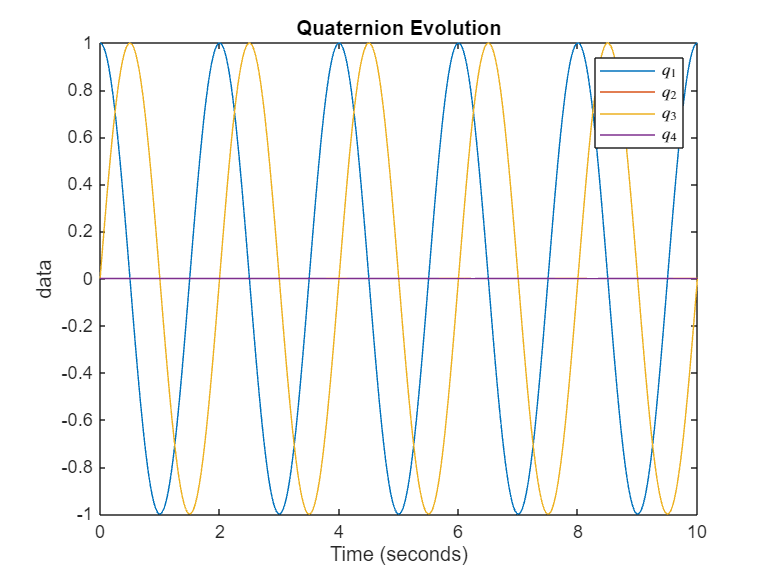


figure(2)
clf
plot(simout.q)
hold on
title('Quaternion Evolution')
legend('$q_1$','$q_2$','$q_3$','$q_4$','Interpreter','latex')

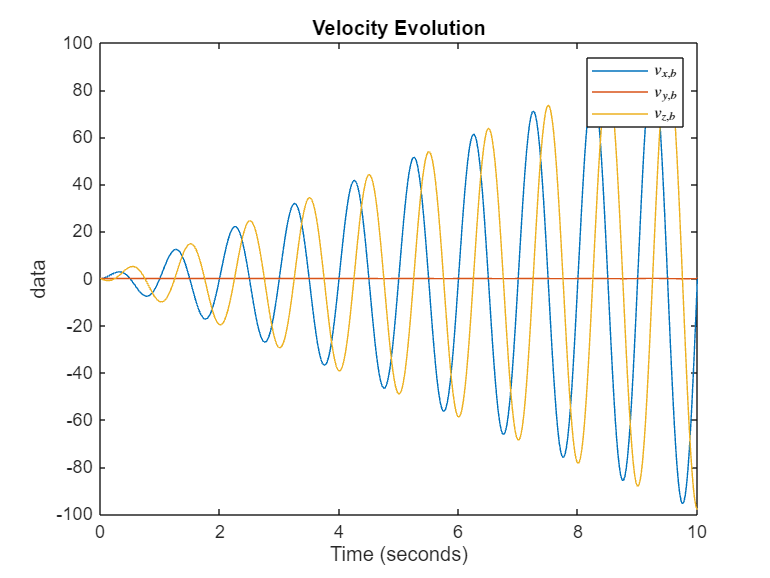


figure(3)
clf
plot(simout.v_b)
hold on
title('Velocity Evolution')
legend('$v_{x,b}$','$v_{y,b}$','$v_{z,b}$','Interpreter','latex')

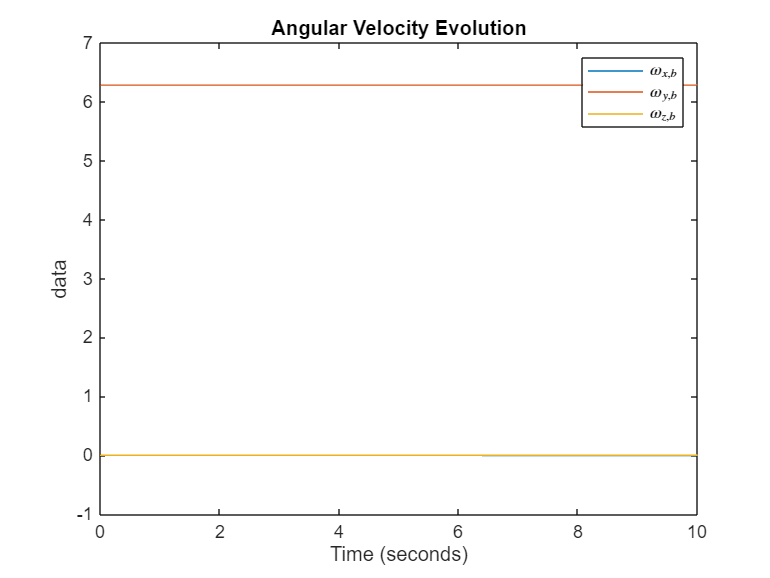


figure(4)
clf
plot(simout.omega_b)
hold on
title('Angular Velocity Evolution')
legend('$\omega_{x,b}$','$\omega_{y,b}$','$\omega_{z,b}$','Interpreter','latex')

Once again, this passes the test! Let's now try the case of the z axis: 

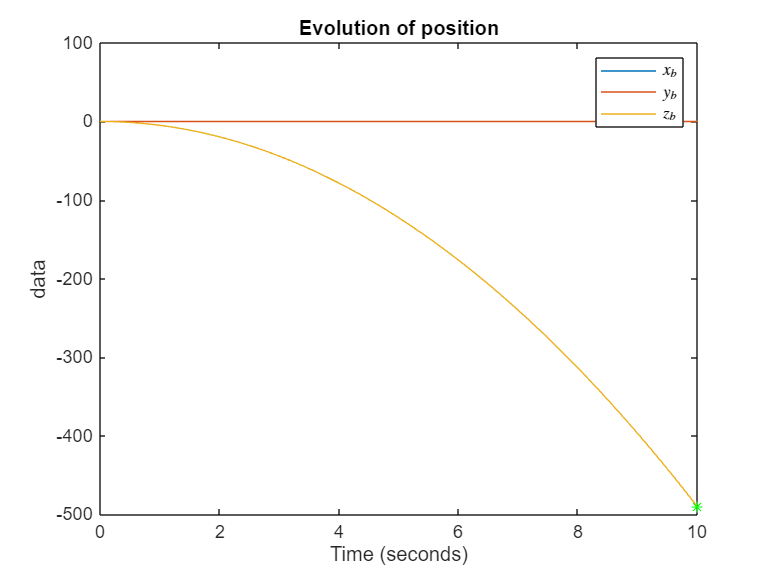

%Case 3: Rotation about z -> major axis
p_b_i_0=[0;0;0];
q_0=[1;0;0;0];

v_b_0=[0;0;0];
omega_b_0=[1e-4;1e-4;2*pi]; %[rad/s]
nu_b_0=[v_b_0;omega_b_0];

simout=sim("Gravity_Dynamics_Model.slx",RelTol='1e-6');

figure(1)
clf
plot(simout.p_b_i)
hold on
plot(10,-g*10^2/2,'g*')
title('Evolution of position')
legend('$x_b$','$y_b$','$z_b$','Interpreter','latex')

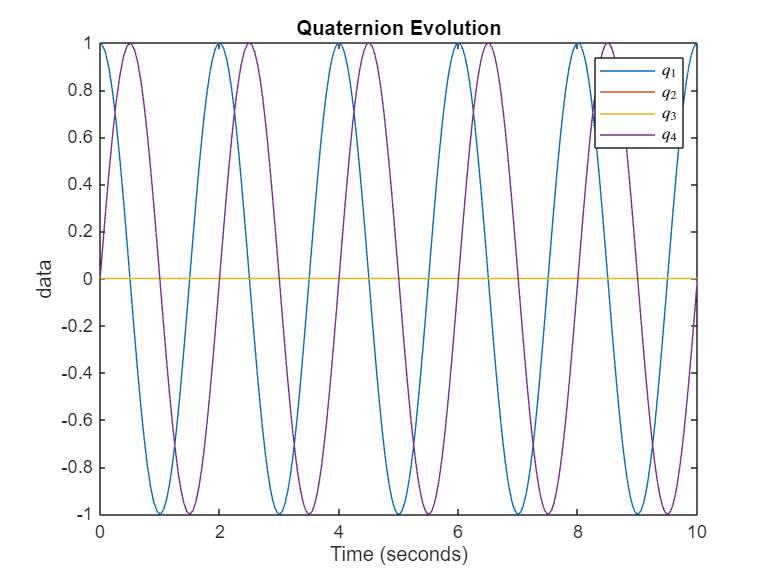


figure(2)
clf
plot(simout.q)
hold on
title('Quaternion Evolution')
legend('$q_1$','$q_2$','$q_3$','$q_4$','Interpreter','latex')

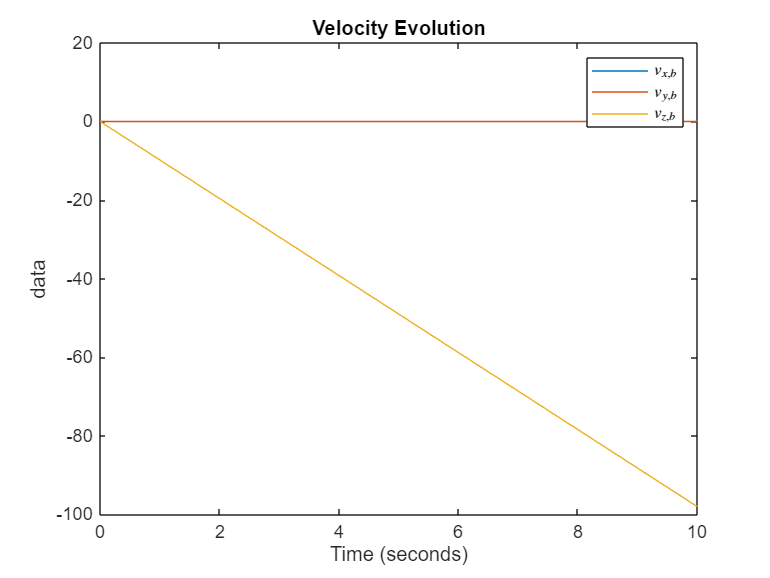


figure(3)
clf
plot(simout.v_b)
hold on
title('Velocity Evolution')
legend('$v_{x,b}$','$v_{y,b}$','$v_{z,b}$','Interpreter','latex')

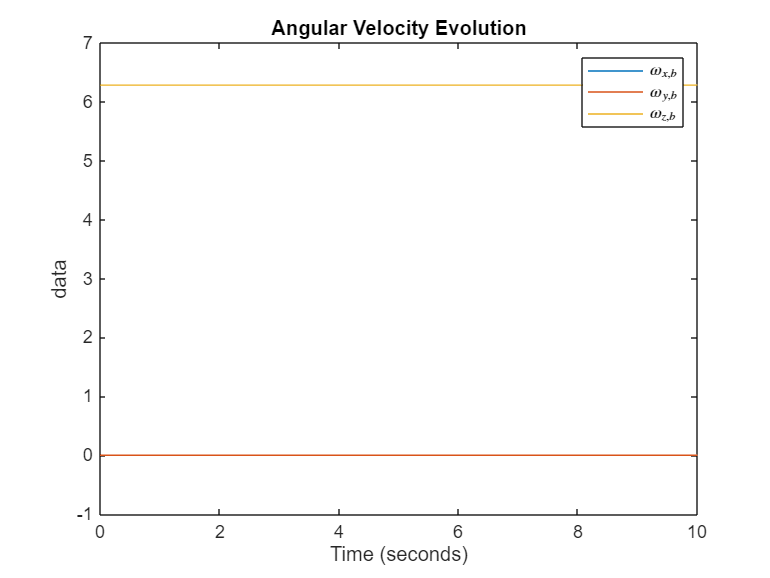


figure(4)
clf
plot(simout.omega_b)
hold on
title('Angular Velocity Evolution')
legend('$\omega_{x,b}$','$\omega_{y,b}$','$\omega_{z,b}$','Interpreter','latex')

A final case will be tried with a modified inertia matrix to see if the intermediate axis instability is captured. 

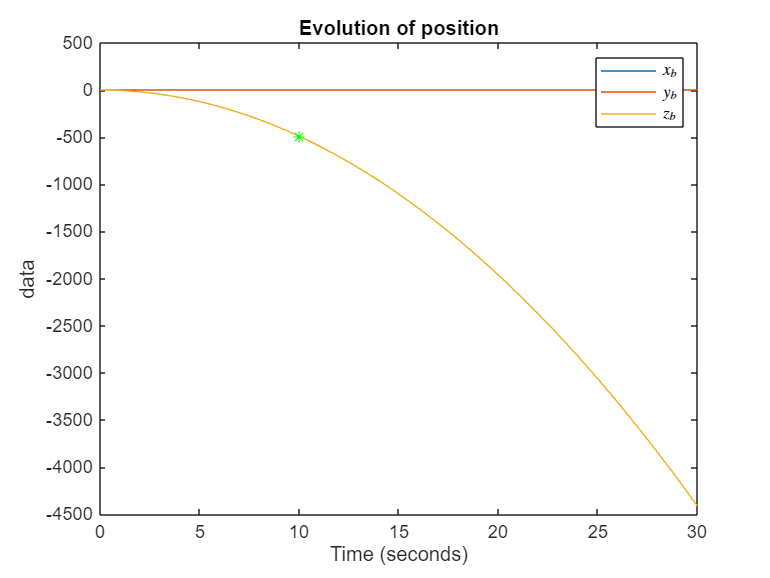

%Case 4: modified rotation around y axis, now made intermediate. 

UAV.J=diag([0.01 0.012 0.018]);
UAV.MM=[UAV.m*eye(3,3),UAV.S';UAV.S,UAV.J];
UAV.MM_inv=inv(UAV.MM);
p_b_i_0=[0;0;0];
q_0=[1;0;0;0];

v_b_0=[0;0;0];
omega_b_0=[1e-4;2*pi;1e-4]; %[rad/s]
nu_b_0=[v_b_0;omega_b_0];

simout=sim("Gravity_Dynamics_Model.slx",StopTime='30');
UAV.J=diag([0.01 0.01 0.018]); %introduced here to undo the change and avoid weird stuff if things are run out of order
UAV.MM=[UAV.m*eye(3,3),UAV.S';UAV.S,UAV.J];
UAV.MM_inv=inv(UAV.MM);

figure(1)
clf
plot(simout.p_b_i)
hold on
plot(10,-g*10^2/2,'g*')
title('Evolution of position')
legend('$x_b$','$y_b$','$z_b$','Interpreter','latex')

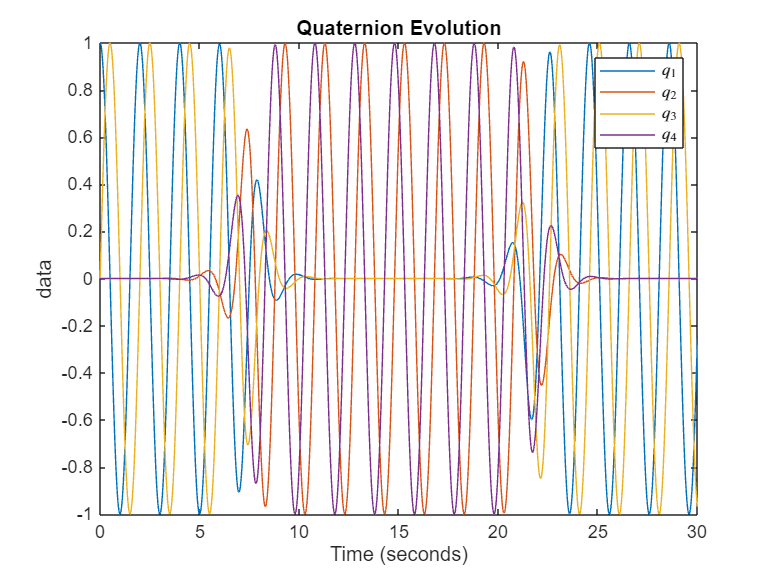


figure(2)
clf
plot(simout.q)
hold on
title('Quaternion Evolution')
legend('$q_1$','$q_2$','$q_3$','$q_4$','Interpreter','latex')

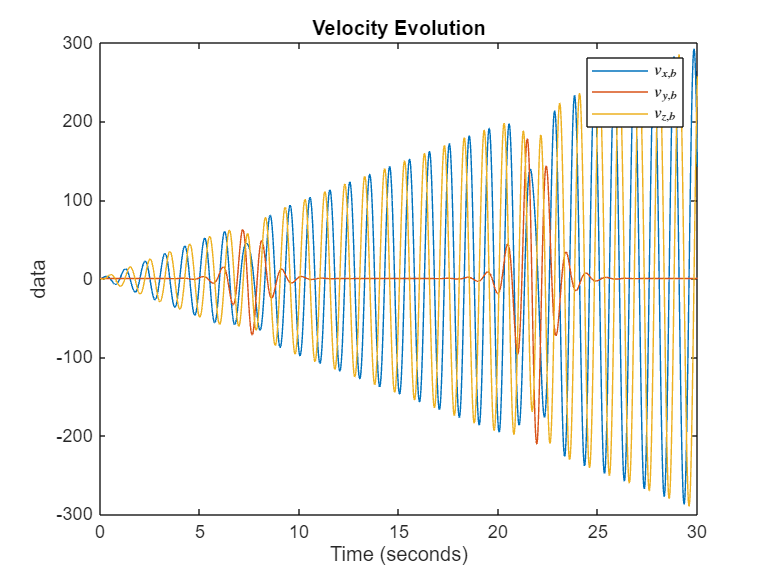


figure(3)
clf
plot(simout.v_b)
hold on
title('Velocity Evolution')
legend('$v_{x,b}$','$v_{y,b}$','$v_{z,b}$','Interpreter','latex')

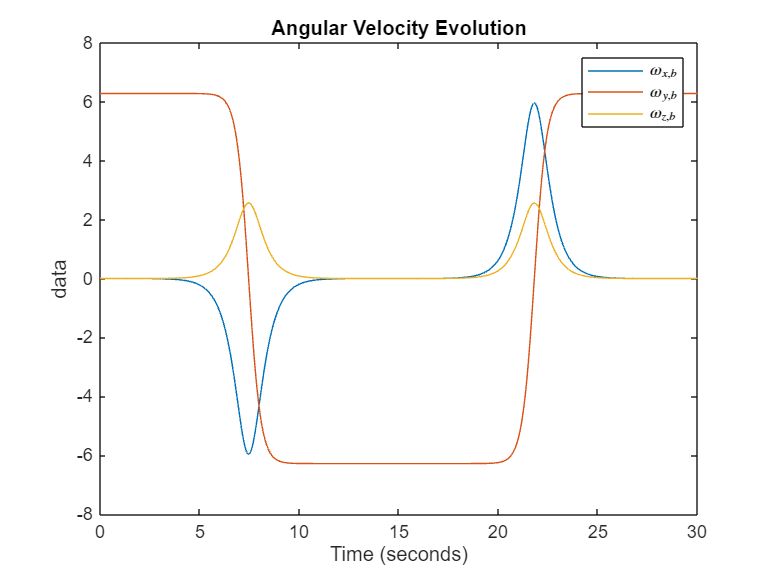


figure(4)
clf
plot(simout.omega_b)
hold on
title('Angular Velocity Evolution')
legend('$\omega_{x,b}$','$\omega_{y,b}$','$\omega_{z,b}$','Interpreter','latex')

With this change, we can actually see the instability of the intermediate axis. With this, I consider this implementation fully validated. 

## Full Model Testing w/o Actuator Dynamics: 

In this part the goal is to augment the previous model with the aerodynamics and control wrench. The way we will validate this is to check if the analytically computed trim conditions are trim conditions in the model. This will be tested in two steps, first without actuators and then with actuators. When analyzing actuators, the bode plots of the actuator system will also be extracted, to get some understanding of their bandwidth for the next tasks. Begin by defining all of the relevant parameters: 

%Define geometric and inertial model parameters: 
UAV.Nr = 6; %number of rotors

UAV.m = 1.2; %[kg] UAV mass

UAV.J = diag([0.01 0.01 0.018]); % [kg m^2] inertia matrix

UAV.r_bg = [0 0 0]'; %[m] center of mass location in the body frame -> note I change it to a column vector. 
UAV.S = UAV.m*cross_matrix(UAV.r_bg); % [kg m] static moment

%Use these to define the relevant matrices: 
UAV.MM=[UAV.m*eye(3,3),UAV.S';UAV.S,UAV.J];
UAV.MM_inv=inv(UAV.MM);

%Specify gravitational acceleration: 
g=9.81; %[m/s^2]

%Introduce aerodynamics: 
% Linear Aerodynamics
UAV.D_tauomega = diag([0.48 0.48 2.37]); %  angular velocity damping 
UAV.D_fv =  diag([0.055 0.055 0.022]); % linear velocity damping

UAV.D = [UAV.D_fv zeros(3,3); zeros(3,3) UAV.D_tauomega]; %-> there is a typo in the position of D_fv and D_tauomega on the data provided by the professor

% Propellers -> input map is WIP. 
UAV.b = 0.215; %[m] arm length (ell in the slides)

k_f = 3.65e-6;                % [N/rad^2/s^2] Thrust characteristic coeff
sigma = 0.09;      % [m] Torque-to-thrust ratio

%Construct input map:
%Rotors 1,3,5 rotate in the positive direction, 2,4,6 rotate in the
%negative direction
xiv=zeros(UAV.Nr,1);
xiv(1:2:UAV.Nr)=1; 
xiv(2:2:UAV.Nr)=-1;

gamma_r=2*pi/UAV.Nr*(0:UAV.Nr-1);
nr=[0;0;1];

F=nan(6,UAV.Nr);
for i=1:UAV.Nr
    pr=UAV.b*[cos(gamma_r(i));sin(gamma_r(i));0];
    pr_x=cross_matrix(pr);
    F(1:3,i)=nr;
    F(4:6,i)=(pr_x-xiv(i)*sigma*eye(3,3))*nr;
end
display(F)

F =          0         0         0         0         0         0
         0         0         0         0         0         0
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
         0    0.1862    0.1862    0.0000   -0.1862   -0.1862
   -0.2150   -0.1075    0.1075    0.2150    0.1075   -0.1075
   -0.0900    0.0900   -0.0900    0.0900   -0.0900    0.0900


 The input map matches with my analytical computation, so I consider it validated. With all parameters defined, the next step is to analyze trim conditions: 

#### Trim Case 1: Position

In this case, the goal is to trim the vehicle at a specified position in hover. Let's initialize the simuation and check the results.

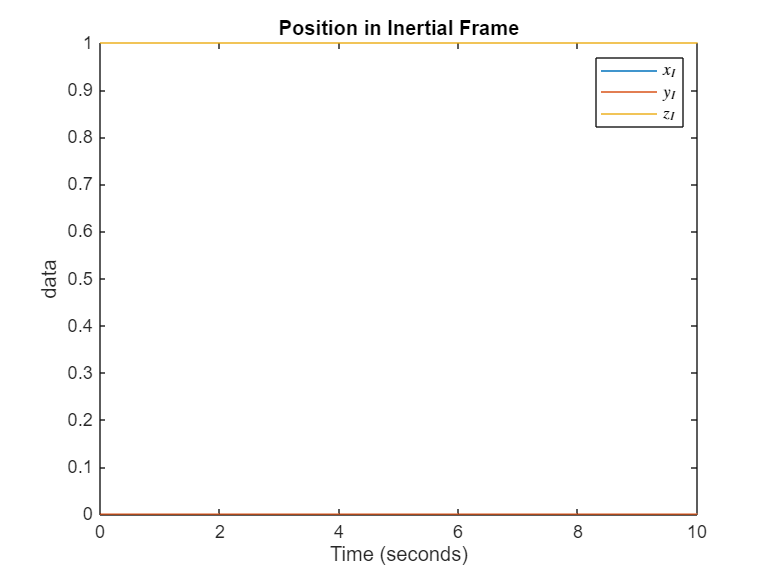

%Set initial conditions: 
p_b_i_0=[0;0;1];
q_0=[1;0;0;0];

v_b_0=[0;0;0];
omega_b_0=[0;0;0]; %[rad/s]
nu_b_0=[v_b_0;omega_b_0];

%Set trim input: 
T_trim=UAV.m*g/6*ones(6,1);

simout=sim("Dynamics_wo_Actuators_Model.slx");

figure(1)
clf
plot(simout.p_b_i)
hold on
title('Position in Inertial Frame')
legend('$x_I$','$y_I$','$z_I$','Interpreter','latex')

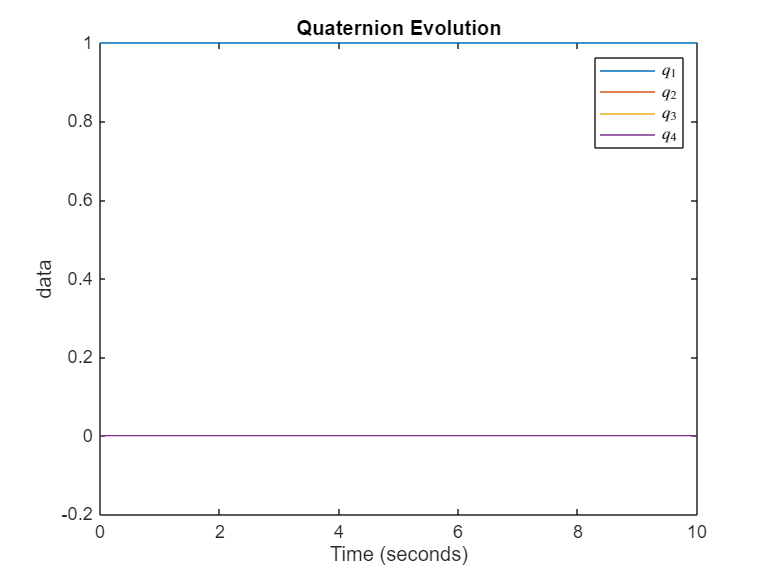


figure(2)
clf
plot(simout.q)
hold on
title('Quaternion Evolution')
legend('$q_1$','$q_2$','$q_3$','$q_4$','Interpreter','latex')

The trim condition is validated. To continue validating the trim conditions and the simulink model, let's handle the second trim condition. 

## Trim 2: Constant Inertial Velocity

Now the goal is to trim the vehicle in forward flight. This means a constant **inertial** linear velocity vector. I will assume no angular velocity. Note that trimming with constant velocity will mean, of course, that the position derivative will be non-null. The position kinematics are simply discarded from the trimming problem.  Look at the paper notes to see the process of analytically trimming the UAV in this condition. 

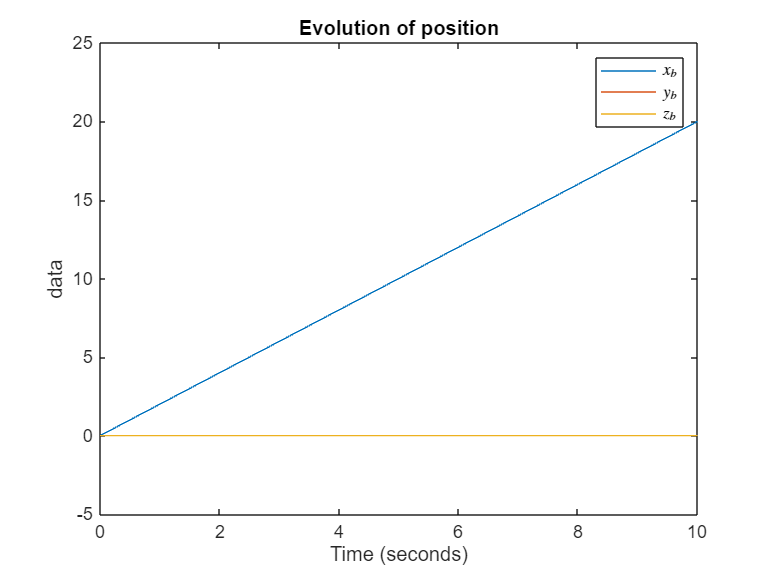

%Set initial conditions for kinematics: 
p_b_i_0=[0;0;0]; %Irrelevant in this case

%Set trim pitch angle and initial quaternion: 
v_i_bar=[2;0;0]; %[m/s]

theta_trim=atan2(UAV.D(1,1)*v_i_bar(1),UAV.m*g);

q_0=[cos(theta_trim/2);0;sin(theta_trim/2);0]; %easy from quaternion definition

%Set initial conditions for dynamics:
%Get T_b_i
eta=q_0(1);
epsilon=q_0(2:4);
epsilon_x=cross_matrix(epsilon);
T_b_i_0=eye(3,3)+2*eta*epsilon_x+2*epsilon_x*epsilon_x;
%Initialize velocities: 
v_b_0=T_b_i_0'*v_i_bar; %do not forget the transpose!
omega_b_0=[0;0;0];
nu_b_0=[v_b_0;omega_b_0];

%Set trim input: 
T_trim=(UAV.D(3,3)*v_i_bar(1)*sin(theta_trim)+UAV.m*g*cos(theta_trim))/6*ones(6,1);

simout=sim("Dynamics_wo_Actuators_Model.slx");

figure
clf
plot(simout.p_b_i)
hold on
title('Evolution of position')
legend('$x_b$','$y_b$','$z_b$','Interpreter','latex')

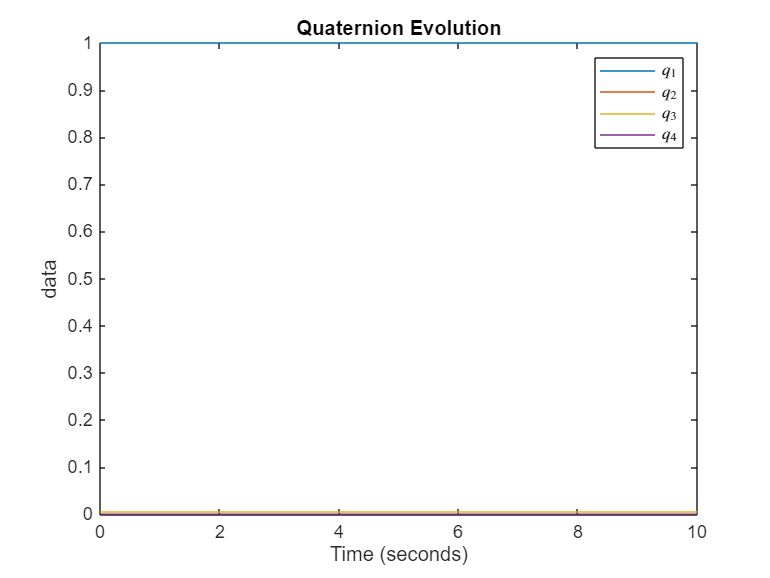



figure
clf
plot(simout.q)
hold on
title('Quaternion Evolution')
legend('$q_1$','$q_2$','$q_3$','$q_4$','Interpreter','latex')

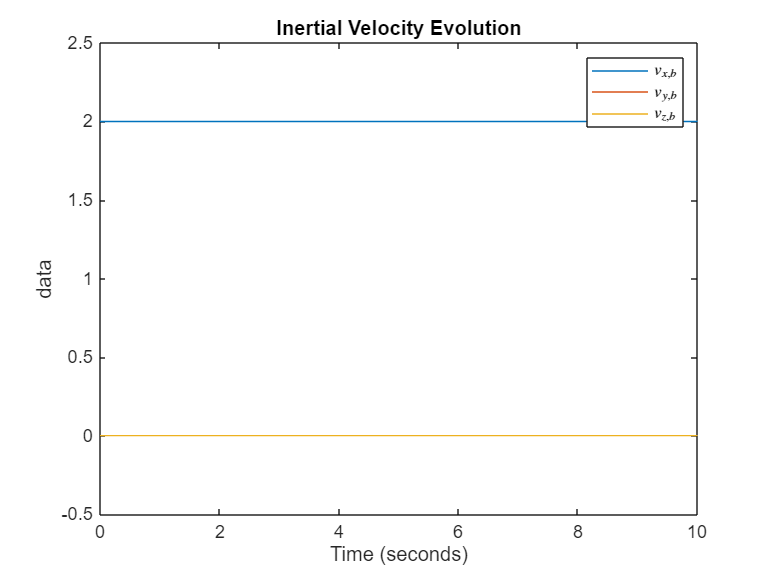


figure
clf
plot(simout.v_i)
hold on
title('Inertial Velocity Evolution')
legend('$v_{x,b}$','$v_{y,b}$','$v_{z,b}$','Interpreter','latex')

The trim condition is also verified in this case. With this, I consider this part of the implementation finished and validated. The next step will be to consider the full dynamics of the model. I will implement it and check it out with the velocity trim case. 

## Full Dynamics: 

This model includes actuator dynamics. They include some non-linearity in the model via the quadratic relation between rotor rpm and thrust. Further nonlinearity is included by means of the saturation function, setting the minimum and maximum values for thrust via a minimum and maximum rpm. Finally, the thrust given by each propeller is scaled by an efficiency factor $\lambda$, which can be tuned at will. 

%Define geometric and inertial model parameters: 
UAV.Nr = 6; %number of rotors

UAV.m = 1.2; %[kg] UAV mass

UAV.J = diag([0.01 0.01 0.018]); % [kg m^2] inertia matrix

UAV.r_bg = [0 0 0]'; %[m] center of mass location in the body frame -> note I change it to a column vector. 
UAV.S = UAV.m*cross_matrix(UAV.r_bg); % [kg m] static moment

%Use these to define the relevant matrices: 
UAV.MM=[UAV.m*eye(3,3),UAV.S';UAV.S,UAV.J];
UAV.MM_inv=inv(UAV.MM);

%Specify gravitational acceleration: 
g=9.81; %[m/s^2]

%Introduce aerodynamics: 
% Linear Aerodynamics
UAV.D_tauomega = diag([0.48 0.48 2.37]); %  angular velocity damping 
UAV.D_fv =  diag([0.055 0.055 0.022]); % linear velocity damping

UAV.D = [UAV.D_fv zeros(3,3); zeros(3,3) UAV.D_tauomega]; %-> there is a typo in the position of D_fv and D_tauomega on the data provided by the professor

% Propellers -> input map is WIP. 
UAV.b = 0.215; %[m] arm length (ell in the slides)

k_f = 3.65e-6;                % [N/rad^2/s^2] Thrust characteristic coeff
sigma = 0.09;      % [m] Torque-to-thrust ratio

%Construct input map:
%Rotors 1,3,5 rotate in the positive direction, 2,4,6 rotate in the
%negative direction
xiv=zeros(UAV.Nr,1);
xiv(1:2:UAV.Nr)=1; 
xiv(2:2:UAV.Nr)=-1;

gamma_r=2*pi/UAV.Nr*(0:UAV.Nr-1);
nr=[0;0;1];

F=nan(6,UAV.Nr);
for i=1:UAV.Nr
    pr=UAV.b*[cos(gamma_r(i));sin(gamma_r(i));0];
    pr_x=cross_matrix(pr);
    F(1:3,i)=nr;
    F(4:6,i)=(pr_x-xiv(i)*sigma*eye(3,3))*nr;
end

%For actuator dynamics: 
UAV.Omega_max = 10300; %[rpm] max spinning rate
UAV.Omega_min = 1260; %[rpm] min spinning rate
UAV.k_m = 1/0.05; % [s-1] Inverse of the time constant of the propeller motors

T_max=k_f*(UAV.Omega_max*2*pi/60)^2; %Unit conversion needed since kf is in N/(rad^2/s^2)
T_min=k_f*(UAV.Omega_min*2*pi/60)^2;

Now that the parameters have been defined, let's test the implementation against the velocity trim condition. Assume ideal propeller efficiency and $\Omega_r$ starting at the trim values. Let's see what happens: 

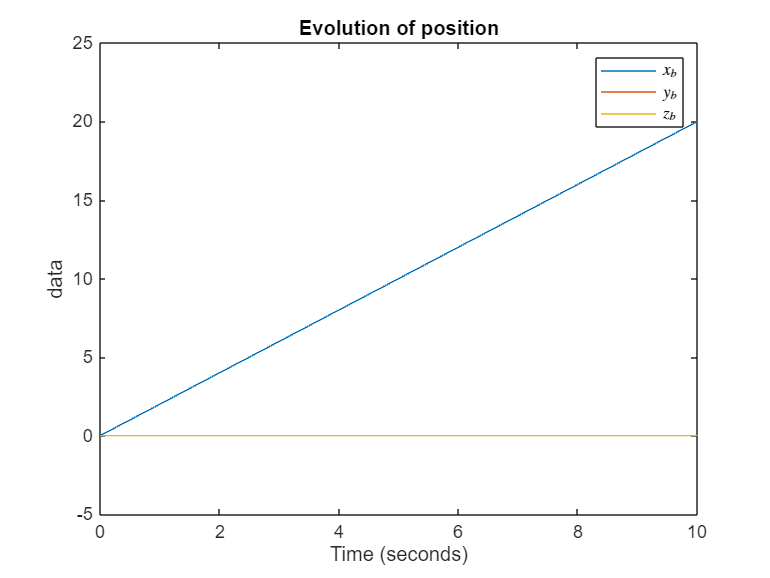

%Set initial conditions for kinematics: 
p_b_i_0=[0;0;0]; %Irrelevant in this case

%Set trim pitch angle and initial quaternion: 
v_i_bar=[2;0;0]; %[m/s]

theta_trim=atan2(UAV.D(1,1)*v_i_bar(1),UAV.m*g);

q_0=[cos(theta_trim/2);0;sin(theta_trim/2);0]; %easy from quaternion definition

%Set initial conditions for dynamics:
%Get T_b_i
eta=q_0(1);
epsilon=q_0(2:4);
epsilon_x=cross_matrix(epsilon);
T_b_i_0=eye(3,3)+2*eta*epsilon_x+2*epsilon_x*epsilon_x;
%Initialize velocities: 
v_b_0=T_b_i_0'*v_i_bar; %do not forget the transpose!
omega_b_0=[0;0;0];
nu_b_0=[v_b_0;omega_b_0];

%Set trim input: 
T_trim=(UAV.D(3,3)*v_i_bar(1)*sin(theta_trim)+UAV.m*g*cos(theta_trim))/6*ones(6,1);

%Initialize actuator dynamics and define propeller efficiencies: 
Lambda=eye(UAV.Nr,UAV.Nr);
Omega_r_0=sqrt(T_trim(1)/k_f)*ones(UAV.Nr,1);

simout=sim("Full_Dynamics_Model.slx");

figure
clf
plot(simout.p_b_i)
hold on
title('Evolution of position')
legend('$x_b$','$y_b$','$z_b$','Interpreter','latex')


figure
clf
plot(simout.q)
hold on
title('Quaternion Evolution')
legend('$q_1$','$q_2$','$q_3$','$q_4$','Interpreter','latex')


figure
clf
plot(simout.v_i)
hold on
title('Inertial Velocity Evolution')
legend('$v_{x,b}$','$v_{y,b}$','$v_{z,b}$','Interpreter','latex')

The trim condition is also verified. So we can consider this implementation successful. I will close the analysis by looking at the bode plot for an actuator, in order to get a feel for their capabilities. 

#### Actuator bode plot:

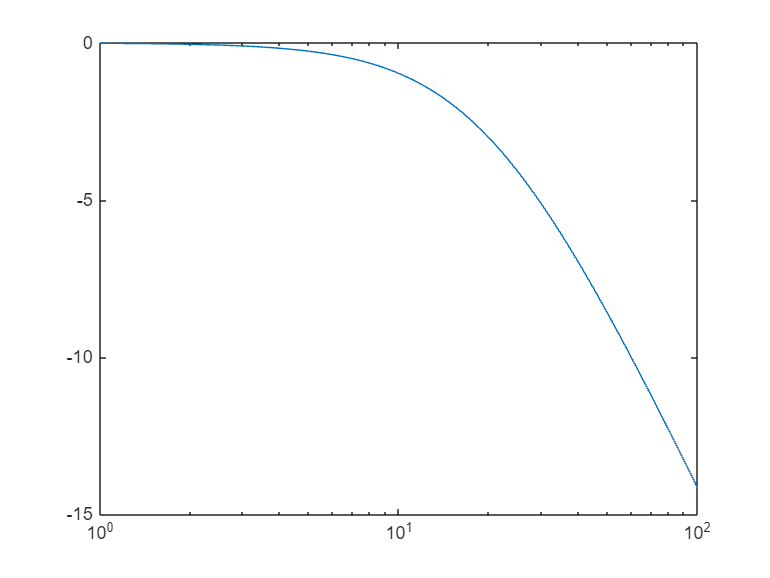

k_m=1/0.05;

A=-k_m;
B=k_m;
C=1;
D=0;

ss_actuator=ss(A,B,C,D);

figure
clf
%bode(ss_actuator)
%bodemag(ss_actuator)
omega_plot=logspace(0,2,100);
freq_response=k_m./(omega_plot*1i+k_m);
semilogx(omega_plot,20*log10(abs(freq_response)))

As expected, it's a first order system with unit gain and a bandwidth of approximately 20 rad/s. Bear this in mind later on when developing controllers. 